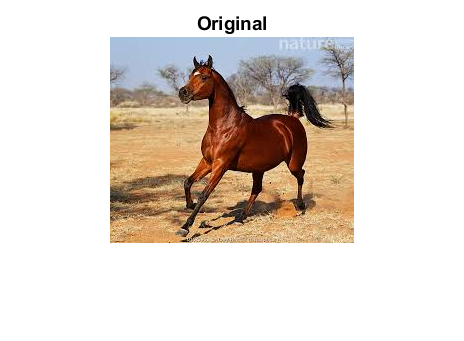

% Use the code for the noisy image to implement three different types
%of noise while keeping the SNR constant. Then, by visual inspection
%only, grade the quality of the images as bad, worse, and worst. The
%three types of noise you may try out are the Gaussian, uniform, and
%Poisson distributions. The fixed SNR is 10 dB.

x = imread('C:\Users\hamma\Downloads\horse.jpeg');
imshow(x)
title('Original');

[r,c,s] = size(x) ;
guassian_noice = imnoise(x,'gaussian',0.5);
salt_and_pepper_noice = imnoise(x,'salt & pepper',0.5);
speckle_noice=imnoise(x,'speckle',0.5);
%uniform_noice=imnoise(x,'uniform',0.5);

Error using imnoise>ParseInputs (line 133)
Unknown noise type: 'uniform'.

Error in imnoise (line 86)
[a, code, classIn, classChanged, p3, p4] = ParseInputs(args{:});

%snr = 20*log10(sum(sum(sum(x.^2)))/sum(sum(sum((y-x).^2)))) ;\
snr=10;
figure
imshow(guassian_noice)
title('Guassian Noice');
figure
imshow(salt_and_pepper_noice)
title('Salt and Pepper Noice');
figure
imshow(speckle_noice)
title('Speckle Noice');
figure
imshow(uniform_noice)
title('uniform Noice');